current=pwd;
folder='\data_3_class';
DatasetPath = strcat(current,folder);
imds22_ = imageDatastore(DatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');



imds22_.ReadFcn = @(loc) cat(3, imresize(imread(loc),[224 224]), imresize(imread(loc),[224 224]), imresize(imread(loc),[224 224]));
[Pred_,prob_] = classify(net2,imds22_,'MiniBatchSize',28);

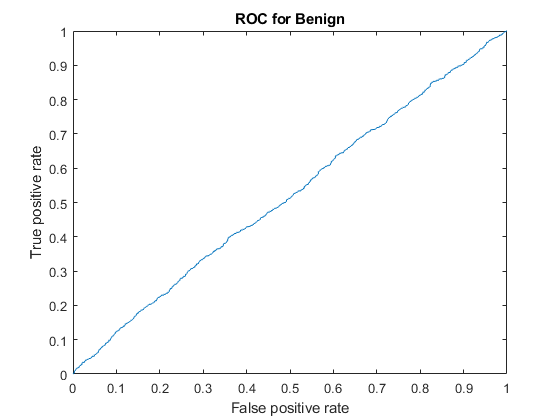


[X,Y,T,AUC] = perfcurve(imds22_.Labels,prob_(:,1),'Benign');
figure
plot(X,Y)
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC for Benign')

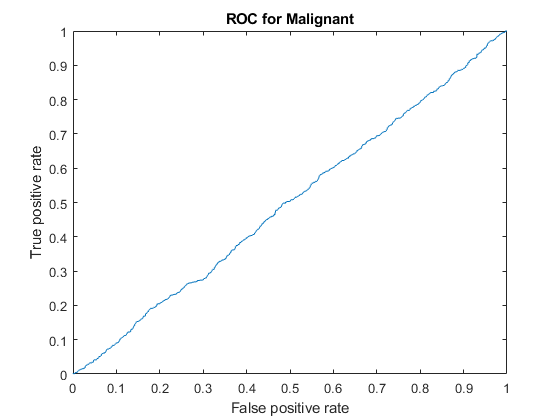


[X2,Y2,T2,AUC2] = perfcurve(imds22_.Labels,prob_(:,2),'Malignant');
figure
plot(X2,Y2)
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC for Malignant')

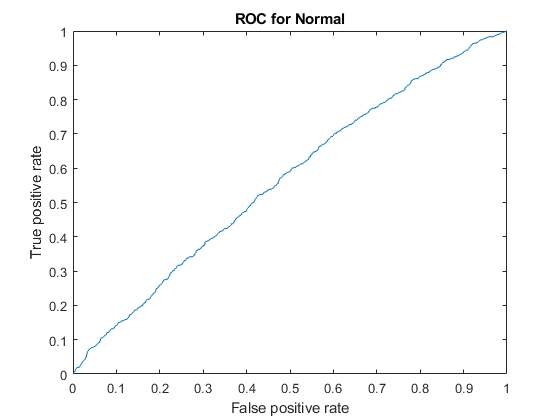


[X3,Y3,T3,AUC3] = perfcurve(imds22_.Labels,prob_(:,3),'NORM_');
figure
plot(X3,Y3)
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC for Normal')